clear
clc
rng('default')

data = readmatrix('dataset-7a.xlsx','Sheet','Q1A');
data = data(:,2:end);

height_s1 = data(:,1);
discharge_s1 = data(:,2);
discharge_s2 = data(:,3);
discharge_s3 = data(:,4);



data = webread('http://192.168.1.50/water/');
all_data = data.data;


s1_data = all_data([all_data.station_id] == 1);
day = [s1_data.Date];

[ll,order] = sort(day);
sorted_q1 = s1_data(order);

s1_height = [sorted_q1.w_height];
height_s1(56:60) = s1_height

height_s1 =   116.5600
  116.8600
  117.1500
  117.3200
  117.4300
  117.5700
  117.6500
  117.6800
  117.6900
  117.6600


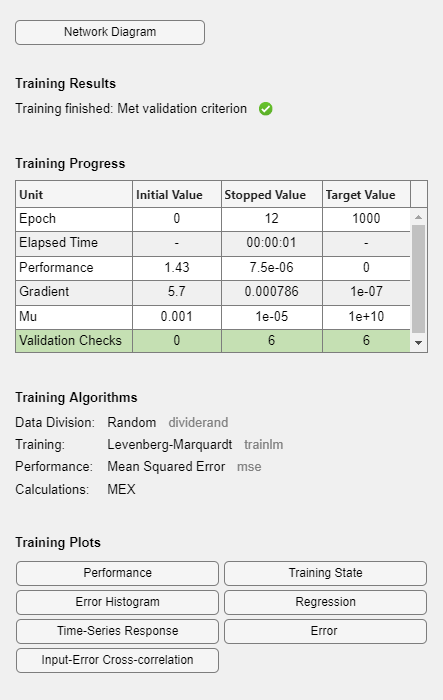

XTrain = num2cell(transpose(height_s1));
TTrain = num2cell((1:45));


N = 10; % Multi-step ahead prediction


inputSeries  = XTrain(1:end-N);
targetSeries = XTrain(1:end-N);

inputSeriesVal  = XTrain(end-N+1:end);

delay = 10;
neuronsHiddenLayer = 5;
% Network Creatio
net = narxnet(1:delay,1:delay,neuronsHiddenLayer);

[Xs,Xi,Ai,Ts] = preparets(net,inputSeries,{},targetSeries); 
net = train(net,Xs,Ts,Xi,Ai);

%view(net)
Y = net(Xs,Xi,Ai); 

perf = perform(net,Ts,Y);
fprintf("Mean square error is %.5f",perf)

Mean square error is 0.00063

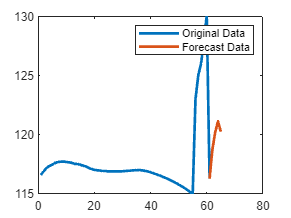


[Xs1,Xio,Aio] = preparets(net,inputSeries(1:end-delay),{},targetSeries(1:end-delay));
[Y1,Xfo,Afo] = net(Xs1,Xio,Aio);
[netc,Xic,Aic] = closeloop(net,Xfo,Afo);
[yPred,Xfc,Afc] = netc(inputSeriesVal,Xic,Aic);


originalData = cell2mat(inputSeries);
forecastData = cell2mat(yPred);
height_s1(61) = forecastData(1);
plot(1:61, height_s1(1:61), 'LineWidth', 2, 'DisplayName', 'Original Data');
hold on
plot(61:65, forecastData(1:5), 'LineWidth', 2, 'DisplayName', 'Forecast Data')
hold off
legend('show')

height_s1(61:65) = forecastData(1:5);



QH_S1 = readmatrix('dataset-7a.xlsx','Sheet','QH_S1');
Q_S1 = QH_S1(:,2);
H_S1 = QH_S1(:,1);

x = H_S1;
y = Q_S1;

% Fit the model to the data
fitResult_S1 = polyfit(x, y, 5);

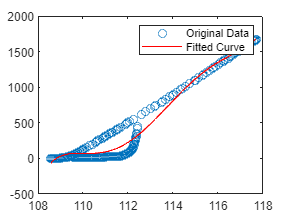



plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;

fittedCurve = polyval(fitResult_S1,x);
plot(x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');

hold off;
legend('show');

MSE = (1/length(y)) * sum((y - fittedCurve).^2);
R_squared = 1 - sum((y - fittedCurve).^2) / sum((y - mean(y)).^2);


disp(['Mean Squared Error (MSE): ' num2str(MSE)]);

Mean Squared Error (MSE): 9660.3982


disp(['R-squared: ' num2str(R_squared)]);

R-squared: 0.96559



% คำนวณค่า Q S1
for n = 56:65
    x_test = height_s1(n);
    discharge_s1(n) = polyval(fitResult_S1,x_test);
end

Q_at_day56to60 = sum(discharge_s1(56:60))

Q_at_day56to60 = 8.8428e+05

Q_at_day61to65 = sum(discharge_s1(61:65))

Q_at_day61to65 = 2.0470e+04

sumQ56to65 = Q_at_day56to60 + Q_at_day61to65

sumQ56to65 = 9.0475e+05

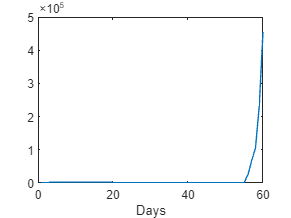

Q_S3_sum = discharge_s1 + discharge_s2;
f = discharge_s3 - discharge_s2 - discharge_s1;
Q3_new = discharge_s1 + discharge_s2 + f;
plot(Q_S3_sum)
xlabel('Days')

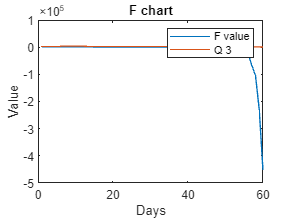

f = discharge_s3 - discharge_s2 - discharge_s1;
plot(f, 'DisplayName', 'F value')
title("F chart")
xlabel('Days')
ylabel('Value')
hold on
plot(discharge_s3, 'DisplayName', 'Q 3')
hold off
legend('show')

%โหลดข้อมูล S3
QH_S3 = readmatrix('dataset-7a.xlsx','Sheet','QH_S3');
Q_S3 = QH_S3(:,2);
H_S3 = QH_S3(:,1);

y = H_S3;
x = Q_S3;

% Fit the model to the data
fitResult_S3 = polyfit(x, y, 5);

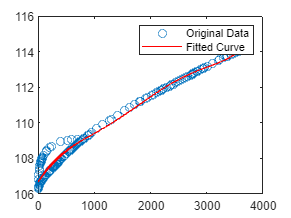



plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;

fittedCurve = polyval(fitResult_S3,x);
plot(x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');

hold off;
legend('show');


residuals = y - fittedCurve;
% Calculate Root Mean Squared Error (RMSE)

MSE = (1/length(y)) * sum((y - fittedCurve).^2);
R_squared = 1 - sum((y - fittedCurve).^2) / sum((y - mean(y)).^2);


disp(['Mean Squared Error (MSE): ' num2str(MSE)]);

Mean Squared Error (MSE): 0.18859


disp(['R-squared: ' num2str(R_squared)]);

R-squared: 0.96177



% คำนวณค่า Q S3
height_s3 = discharge_s3;
for n = 1:length(height_s3)
    x_test = discharge_s3(n);
    height_s3(n) = polyval(fitResult_S3,x_test);
end
height_s3

height_s3 =   113.2427
  113.3951
  113.5861
  113.8151
  113.9885
  114.1158
  114.2587
  114.3252
  114.3252
  114.3027


% data = webread('http://192.168.1.38/water/');
% all_data = data.data;
% 
% 
% s1_data = all_data([all_data.Station_id] == 1);
% day = [s1_data.Date];
% 
% [ll,order] = sort(day);
% sorted_q1 = s1_data(order);
% 
% s1_height = [sorted_q1.w_height];
% s1_height


URL = 'http://192.168.1.50/water/';

for n = 1:60
    h = height_s3(n);
    q = discharge_s3(n);
    dataPost.station_id = 3;
    dataPost.Date = n;
    dataPost.w_height = h;
    dataPost.w_discharge = q;
    options = weboptions('MediaType','application/json');
    response = webwrite(URL,dataPost,options)
end

response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


response = struct with fields:
       data: [1×1 struct]
       code: 200
    message: 'Water added successfully.'


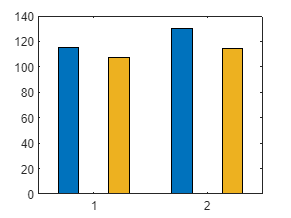

min_height_s1 = min(height_s1);
min_q_s1 = min(discharge_s1);

min_height_s2 = 0;
min_q_s2 = min(discharge_s2);

min_height_s3 = min(height_s3);
min_q_s3 = min(discharge_s3);
%-------------------------------
max_height_s1 = max(height_s1);
max_q_s1 = max(discharge_s1);

max_height_s2 = 0;
max_q_s2 = max(discharge_s2);

max_height_s3 = max(height_s3);
max_q_s3 = max(discharge_s3);
%-------------------------------

plot_barr = [min_height_s1,min_height_s2,min_height_s3
            max_height_s1,max_height_s2,max_height_s3];
figure
title("Min Max of S1 S3")
bar(plot_barr);


fprintf("Min Height of station 1 is %.f m\n",min_height_s1);

Min Height of station 1 is 115 m


fprintf("Min Speed of station 1 is %.f m^3/s\n",min_q_s1);

Min Speed of station 1 is 1094 m^3/s


fprintf("Min Height of station 3 is %.f m\n",min_height_s3);

Min Height of station 3 is 107 m


fprintf("Min Speed of station 3 is %.f m^3/s\n",min_q_s3);

Min Speed of station 3 is 180 m^3/s


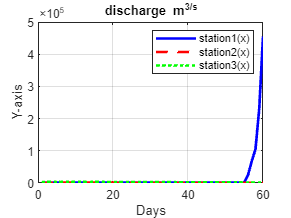


x = (1:60);
y1 = discharge_s1(1:60);
y2 = discharge_s2(1:60);
y3 = discharge_s3(1:60);

% Plot the three lines
plot(x, y1, '-b', 'LineWidth', 2, 'DisplayName', 'station1(x)');
hold on;
plot(x, y2, '--r', 'LineWidth', 2, 'DisplayName', 'station2(x)');
plot(x, y3, ':g', 'LineWidth', 2, 'DisplayName', 'station3(x)');

% Add labels and title
xlabel('Days');
ylabel('Y-axis');
title('discharge m^3/s');
legend('show');
grid on;
hold off;

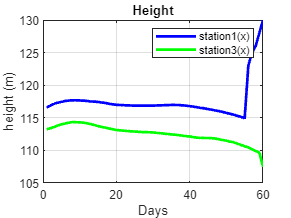

x = (1:60);
y1 = height_s1(1:60);
y3 = height_s3(1:60);



% Plot the three lines
plot(x, y1, '-b', 'LineWidth', 2, 'DisplayName', 'station1(x)');
hold on;
plot(x, y3, '-g', 'LineWidth', 2, 'DisplayName', 'station3(x)');


% Add labels and title
xlabel('Days');
ylabel('height (m)');
title('Height');
legend('show');
grid on;
hold off;